# GIVEN A SINGLE OVERLOAD LOAD-TIME HISTORY

A SAMPLE LOAD TIME HISTORY FOR 

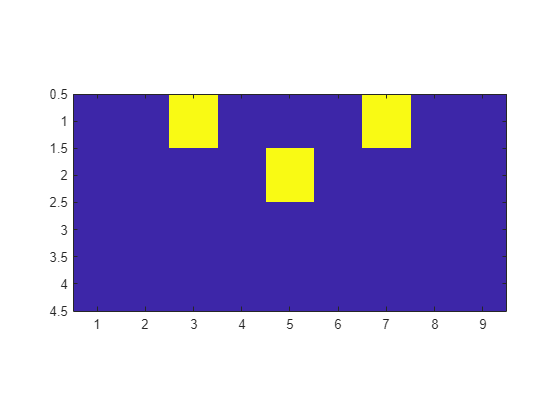

% -------------------- Test reversal history ----------------------------
close all
smin = [0 0 0 0 0 0 0 0 0]';
smax = [3 4 5 1 4 3 5 2 1.8]';
x = pv2revs(smax, smin);
x = [x(:,2); 0];
% -----------------------------------------------------------------------
tic
% -------- Run OL identifier using non-cumulative metrix omega_temp -----
Omega = OLSpectrum(x,1,0);
OLI = OLIndex_nc(Omega, 1);
imagesc(OLI), pbaspect([2 1 1])

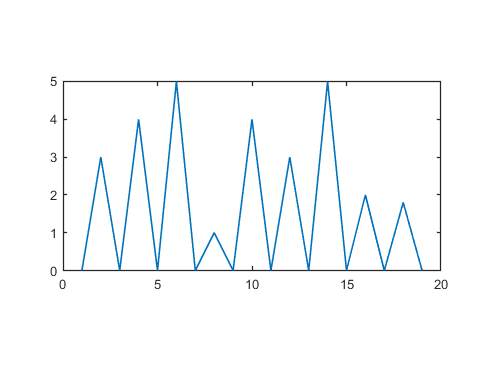

% -------------------- Test reversal history ----------------------------
close all
smin = [0 0 0 0 0 0 0 0 0]';
smax = [3 4 5 1 4 3 5 2 1.8]';
x = pv2revs(smax, smin);
x = [x(:,2); 0];
plot(x)
pbaspect([2 1 1])

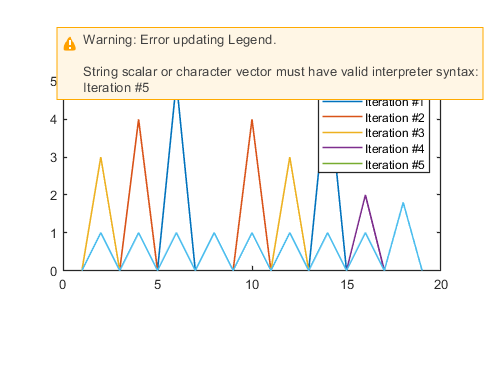

[sigmamax, ~, ~, ~, ~, ~, ~, ~] = drivefactor(x, 'true'); 
% -----------------------------------------------------------------------
tic
% -------------------- Run OL identifier --------------------------------
Omega = OLSpectrum(x, 'True');

% -----------------------------------------------------------------------

% -------------------- Run OL sifter ------------------------------------
OLI = OLIndex(Omega, 1);
% -----------------------------------------------------------------------
toc
imagesc(OLI)
pbaspect([2 1 1])
oli = [1:size(OLI,2); OLI(size(OLI,1),:)];
olindx = oli(1,oli(2,:)~=0);

plot(x)
hold on
plot(sigmamax(olindx,1),sigmamax(olindx,2),'v')
pbaspect([2 1 1])

% -------------------- Decreasing Periodic history ----------------------------
close all
smin = [0 0 0 0 0 0 0 0]';
smax = [4 3 2 1 4 3 2 1]';
repetition = 1;
x = pv2revs(smax, smin);
x = [repmat(x(:,2),repetition,1); 0];
pbaspect([2 1 1])
[sigmamax, ~, ~, ~, ~, ~, ~, ~] = drivefactor(x, 'true'); 
% -----------------------------------------------------------------------
tic
% -------------------- Run OL identifier --------------------------------
Omega = OLSpectrum(x, 'True');
% -----------------------------------------------------------------------

% -------------------- Run OL sifter ------------------------------------
OLI = OLIndex(Omega, 1);
% -----------------------------------------------------------------------
toc

Elapsed time is 0.048129 seconds.


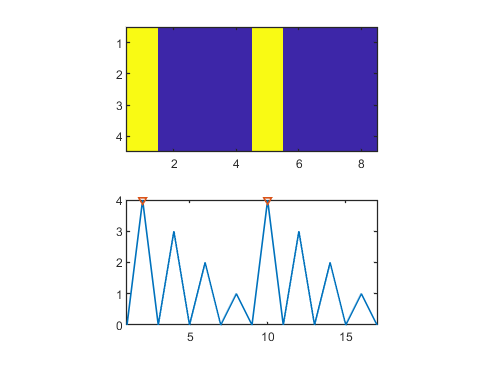


subplot(211)
imagesc(OLI)
pbaspect([2 1 1])
oli = [1:size(OLI,2); OLI(size(OLI,1),:)];
olindx = oli(1,oli(2,:)~=0);
subplot(212)
plot(x)
hold on
plot(sigmamax(olindx,1),sigmamax(olindx,2),'v')
pbaspect([2 1 1])
axis tight

% -------------------- Test reversal history ----------------------------
rng(1);
smin = [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]';
smax = randi(10,1,length(smin))';
x = pv2revs(smax, smin);
x = [x(:,2); 0];
plot(x)

[sigmamax, sigmamin, lcr, ~, ~, ~, ~, ~] = drivefactor(x, 'true'); % call drivefactor for Smax, Smin, and \Delta S
% sigmamax(:,1) = 2:2:length(sigmamax(:,1))*2; % Assign indeces correspond to the maximum stress (even indeces)
sigmamax(sigmamax(:,2) < 0 ,2) = 0;
% -----------------------------------------------------------------------

% -------------------- Run OL identifier --------------------------------
Omega = OLSpectrum(x, 'True');
% -----------------------------------------------------------------------

% -------------------- Run OL sifter ------------------------------------
OLI = OLIndex(Omega, 1);
OLI = OLIndex(OLI, 1);
imagesc(OLI)

oli = [1:size(OLI,2); OLI(size(OLI,1),:)];
olindx = oli(1,oli(2,:)~=0);

plot(x)
hold on
plot(sigmamax(olindx,1),sigmamax(olindx,2),'v')